# Análisis espacio-temporal de la Cuenca del Río Pánuco

import matlab.io.hdfeos.*;
clearvars -except study_area;

%directorio de datos
dir_data = "D:\DATA\";
modis_product = 'MOD13Q1';
kml_file = "RH26";
% umbral para ajuste de ventana y datos 
umbral_mapa=0.1;
umbral_datos = 0.09;
% Cargar los datos en los arreglos
anio_inicio = 2023;
m_cargar_datos

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1098 archivos
>>>>> Obteniendo la zona de estudio
D:\DATA\MOD13Q1\061\*.hdf
>>>>> Analizando 1098 archivos
>>>>> Obteniendo latitud y longitud
>>> Cargando área de estudio
>>> Área de estudio existente 1


## Promedio y desviación estandar de NDVI

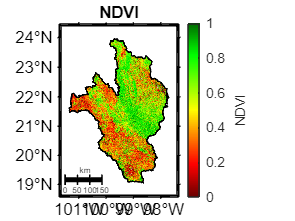

tam_letra=12;

ndvi_prom = f_mean_3dpp(arr_ndvi_mj);
ndvi_prom(study_area==false)=nan;

figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"NDVI",[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,kml_file,1,'k');
exportgraphics(gca,"img/aet_promedio_ndvi.png",'Resolution',300) 

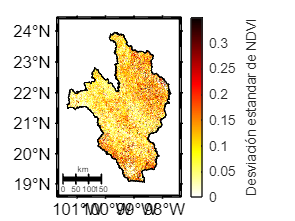


ndvi_std = f_std_3dpp (arr_ndvi_mj);
ndvi_prom(study_area==false)=nan;

figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi_std,flipud( colormap("hot")),[0 0.35],"Desviación estandar de NDVI");
f_draw_kml(dir_data,kml_file,1,'k');
exportgraphics(gca,"img/aet_std_ndvi.png",'Resolution',300);

## Filtrar infromación por estación serie de tiempo

% Los años que se desean consultar
estaciones = 1:4;
anios = 2023:2023;

% Arreglo donde se almacenara el promedio de NDVI por estación
tbl_prom_estacion = zeros(length(anios),length(estaciones));
tbl_desve_estacion = zeros(length(anios),length(estaciones));

%generar las etiquetas de año y estación
lbl_estaciones = ["Primavera","Verano","Otoño","Invierno"];
lbl_ejex_estaciones = string(1: length(anios)*length(estaciones));
a=1;
for i=anios
    for j=estaciones
        if j==1
            %lbl_ejex_estaciones (a) = strcat( lbl_estaciones(j)," ",""+i);
            lbl_ejex_estaciones (a) = strcat(""+i);
        else
            lbl_ejex_estaciones (a)="";
        end
        a=a+1;
    end
end

 
bp=waitbar(0,'Filtrando información por estación x año'); 

for y= 1:length(anios)
    for m = 1:length(estaciones)
        tmp =  find(  info_consulta.anio == anios(y) & info_consulta.estacion == m );
    
        if( isempty (tmp))
            continue;
        end
        tbl_prom_estacion(y,m) = mean(arr_ndvi_mj (:,:,tmp),"all","omitnan");
        tbl_desve_estacion(y,m) = std(arr_ndvi_mj (:,:,tmp),0,"all","omitnan");
        
    end
    waitbar(y/length(anios),bp,sprintf('Año: (%4d) ',anios(y)));

end
close(bp); 

tbl_prom_estacion2=tbl_prom_estacion';
serie_prom_estacion = reshape( tbl_prom_estacion2,[],1);

tbl_desve_estacion2=tbl_desve_estacion';
serie_desve_estacion = reshape( tbl_desve_estacion2,[],1);

## Resultados

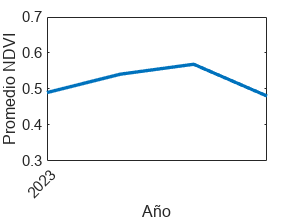



figure;
plot(1:length(serie_prom_estacion),serie_prom_estacion,LineWidth=2);

xlabel('Año');
ylabel('Promedio NDVI');
% xticklabels(lbl_ejex_estaciones);
% xticks(1:length(serie_prom_estacion));
xticklabels(anios);
xticks(1:4:length(serie_prom_estacion));
xtickangle(45);
ylim([0.3 0.7]);
xlim([1 length(serie_prom_estacion)]);
% 
% hold on
% er=errorbar(1:length(serie_prom_estacion),serie_prom_estacion,serie_desve_estacion); 
% er.Color = [0 0 0];                            
% er.LineStyle = 'none';  
% hold off
% 
exportgraphics(gca,"img/aet_promedio_año_estacion.png",'Resolution',300);

## Filtrar información por estación (mapas)

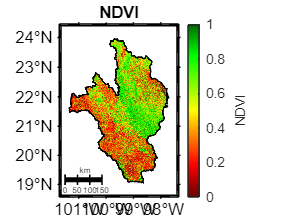

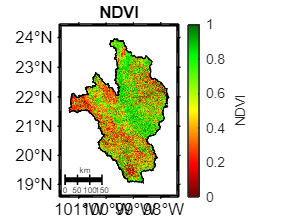

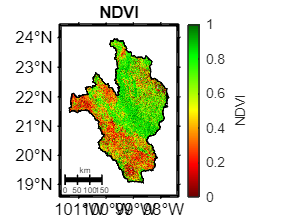

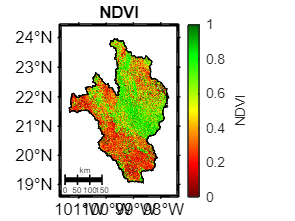

% Arreglo para mapa
mapa_prom_estacion = zeros(ndvi_tam(1),ndvi_tam(2), length(estaciones));

x=1;   
bp=waitbar(0,'Filtrando información por estación'); 

for m = 1:length(estaciones)
    tmp =  find(  info_consulta.estacion == m );

    if( isempty (tmp))
        continue;
    end
    mapa_prom = f_mean_3dpp ( arr_ndvi_mj(:,:,tmp) );
    mapa_prom_estacion(:,:,m) = mapa_prom;

    mapa_prom(study_area==false)=nan;
    figure;
    f_draw_map(lon_mapa,lat_mapa,lon,lat,mapa_prom,"NDVI",[0 1],"NDVI","NDVI");
    f_draw_kml(dir_data,kml_file);
    exportgraphics(gca,"img/aet_promedio_estacion_"+m+".png",'Resolution',300);

    waitbar(m/length(estaciones),bp,sprintf('Estación: (%d) ',estaciones(m)));

end

close(bp); 

## Filtrar información por años

% Los años que se desean consultar
anios = 2000:2022;

% Arreglo donde se almacenara el promedio de NDVI por estación
tbl_prom_anios = zeros(1,length(anios));
tbl_desve_anios = zeros(1,length(anios));

lbl_ejex = string(1: length(anios));
for i=anios
    lbl_ejex (a)=""+i;
end
 
bp=waitbar(0,'Filtrando información por año'); 

for y= 1:length(anios)
        tmp =  find(  info_consulta.anio == anios(y)  );
    
        if( isempty (tmp))
            continue;
        end
        tbl_prom_anios(y) = mean(arr_ndvi_mj (:,:,tmp),"all","omitnan");
        tbl_desve_anios(y) = std(arr_ndvi_mj (:,:,tmp),0,"all","omitnan");
        
    
    waitbar(y/length(anios),bp,sprintf('Año: (%4d) ',anios(y)));

end
close(bp); 


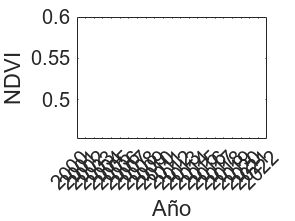

figure;
plot(1:length(tbl_prom_anios),tbl_prom_anios,LineWidth=2);

xlabel('Año');
ylabel('NDVI');
xticklabels(anios);
%xticks(1:23);
xticks(1:length(anios));
xtickangle(45);
ylim([0.453 0.6]);
xlim([1 length(tbl_prom_anios)]);

xticklabels(anios);



% hold on
% er=errorbar(1:length(tbl_prom_anios),tbl_prom_anios,tbl_desve_anios); 
% er.Color = [0 0 0];                            
% er.LineStyle = 'none';  
% hold off

ax = gca;
ax.FontSize=12; 
exportgraphics(gca,"img/aet_promedio_año.png",'Resolution',300);

## Filtrar infromación por mes por año serie de tiempo

% Los años que se desean consultar
meses = 1:12;
anios = 2000:2022;

% Arreglo donde se almacenara el promedio de NDVI por estación
tbl_prom_meses = zeros(length(anios),length(meses));
tbl_desve_meses = zeros(length(anios),length(meses));

%generar las etiquetas de año y estación
lbl_meses = ["Ene","Febrero","Marzo","Abril","Mayo","Junio","Julio","Agosto","Septiembre","Octubre","Noviembre","Diciembre"];
lbl_ejex_meses = string(1: length(anios)*length(meses));
a=1;
for i=anios
    for j=estaciones
        if j==1
            lbl_ejex_meses (a) = strcat( lbl_meses(j)," ",""+i);
            a=a+1;
%          else
%              lbl_ejex_meses (a)="";
        end
        
    end
end

 
bp=waitbar(0,'Filtrando información por estación x año'); 

for y= 1:length(anios)
    for m = meses
        tmp =  find(  info_consulta.anio == anios(y) & info_consulta.mes == m );
    
        if( isempty (tmp))
%             tmp =  find(  info_hdf.mes == m );
%             %% FIX BUG :::(((
%             tbl_prom_meses(y,m) = mean(arr_ndvi_mj (:,:,:),"all","omitnan");
%             tbl_desve_meses(y,m) = std(arr_ndvi_mj (:,:,:),0,"all","omitnan");
            continue;   
        end
        tbl_prom_meses(y,m) = mean(arr_ndvi_mj (:,:,tmp),"all","omitnan");
        tbl_desve_meses(y,m) = std(arr_ndvi_mj (:,:,tmp),0,"all","omitnan");
        
    end
    waitbar(y/length(anios),bp,sprintf('Año: (%4d) ',anios(y)));

end
close(bp); 

tbl_prom_meses2=tbl_prom_meses';
serie_prom_meses = reshape( tbl_prom_meses2,[],1);

tbl_desve_meses2=tbl_desve_meses';
serie_desve_meses = reshape( tbl_desve_meses2,[],1);

## Resultados

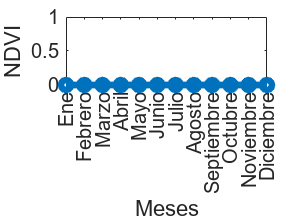

figure;
prom = mean(tbl_prom_meses);
desv = mean(tbl_desve_meses);
plot(1:12,prom,"-o",LineWidth=4);

xlabel('Meses','FontSize',18);
ylabel('NDVI','FontSize',18);
xticklabels(lbl_meses);
xticks(1:12);
ylim([0 1]);
xlim([1 12]);

% hold on
% er=errorbar(1:12,prom,desv); 
% er.Color = [0 0 0];                            
% er.LineStyle = 'none';  
% hold off

ax = gca;
ax.FontSize=12; 
exportgraphics(gca,"img/aet_promedio_x_año_mes.png",'Resolution',300);